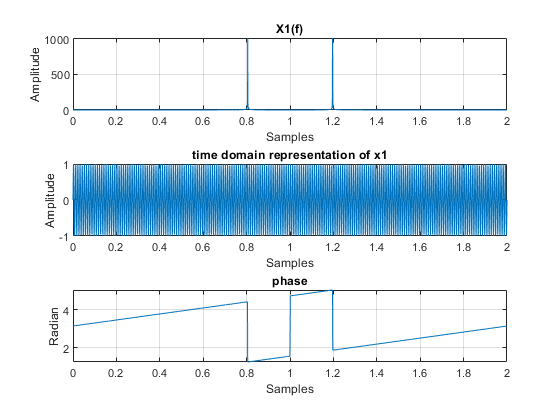

f0 = 100;
t = linspace(0, 2, 2 ^ 11);
Ts = t(2) - t(1);
fs = 1 / Ts;
x1 = sin(2 * pi * f0 * t);
x2 = chirp(t, 200, 2, 400);
x3 = 50 * [zeros(1, 1023) 1 zeros(1, 1024)];
x3 = x1 + x2 + x3;

figure('Name', 'Signal x1');
subplot(3, 1, 1);
plot(t, abs(fftshift(fft(x1))));
xlabel('Samples');
ylabel('Amplitude');
title('X1(f)');
grid on;
subplot(3, 1, 2);
plot(t, x1);
xlabel('Samples');
ylabel('Amplitude');
grid on;
title('time domain representation of x1');
subplot(3, 1, 3);
plot(t, unwrap(angle(fftshift(fft(x1)))));
xlabel('Samples');
ylabel('Radian');
grid on;
title('phase');

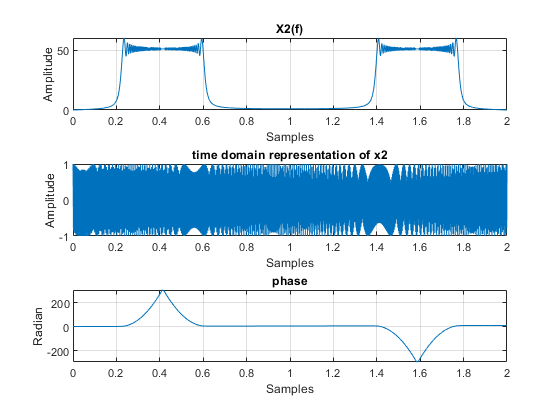


figure('Name', 'Signal x2');
subplot(3, 1, 1);
plot(t, abs(fftshift(fft(x2))));
xlabel('Samples');
ylabel('Amplitude');
title('X2(f)');
grid on;
subplot(3, 1, 2);
plot(t, x2);
xlabel('Samples');
ylabel('Amplitude');
grid on;
title('time domain representation of x2');
subplot(3, 1, 3);
plot(t, unwrap(angle(fftshift(fft(x2)))));
xlabel('Samples');
ylabel('Radian');
grid on;
title('phase');

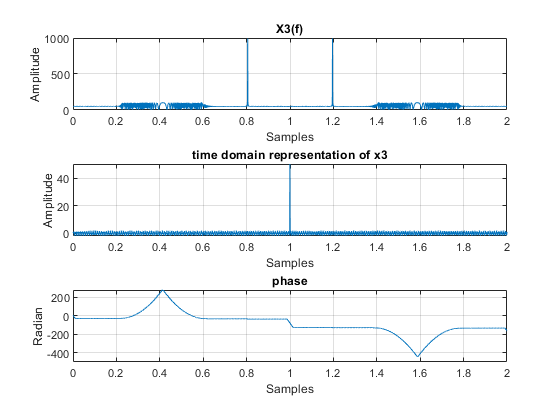


figure('Name', 'Signal x3');
subplot(3, 1, 1);
plot(t, abs(fftshift(fft(x3))));
xlabel('Samples');
ylabel('Amplitude');
title('X3(f)');
grid on;
subplot(3, 1, 2);
plot(t, x3);
xlabel('Samples');
ylabel('Amplitude');
grid on;
title('time domain representation of x3');
subplot(3, 1, 3);
plot(t, unwrap(angle(fftshift(fft(x3)))));
xlabel('Samples');
ylabel('Radian');
grid on;
title('phase');

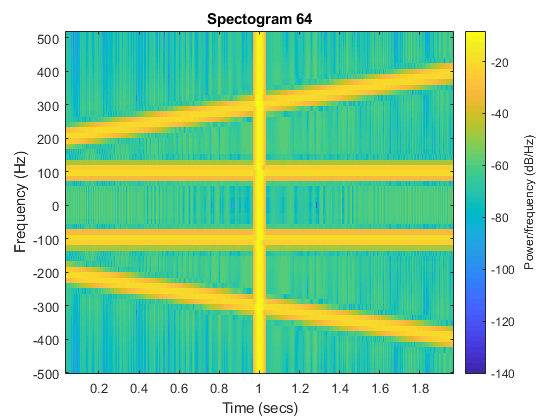


w1 = hamming(64);
figure('Name', 'Hamming');
spectrogram(x3, w1, 63, 64, fs, 'centered', 'yaxis');
title('Spectogram 64');

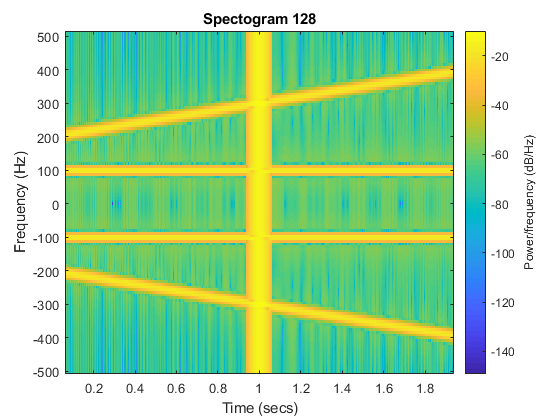


w2 = hamming(128);
figure('Name', 'Hamming');
spectrogram(x3, w2, 127, 128, fs, 'centered', 'yaxis');
title('Spectogram 128');

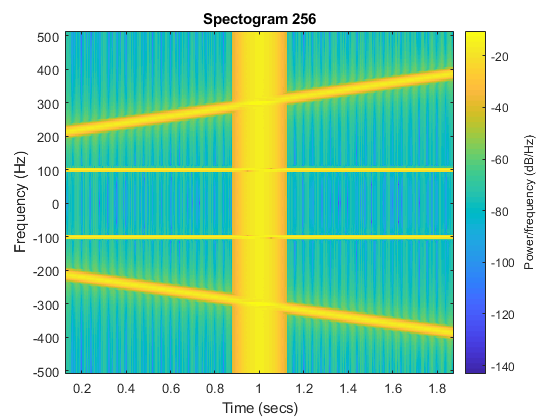


w3 = hamming(256);
figure('Name', 'Hamming');
spectrogram(x3, w3, 255, 256, fs, 'centered', 'yaxis');
title('Spectogram 256');

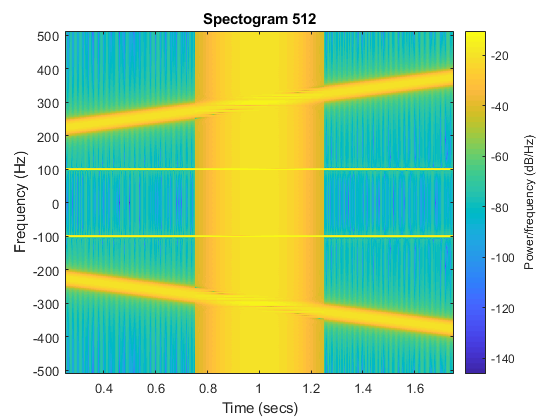


w4 = hamming(512);
figure('Name', 'Hamming');
spectrogram(x3, w4, 511, 512, fs, 'centered', 'yaxis');
title('Spectogram 512');


[s, t, f] = stft(x3, fs, 'window', w2, 'OverLapLength', 127, 'FFTLength', 128);

Undefined function or variable 'stft'.

figure('Name', 'STFT');
surf(f, t, abs(s), 'EdgeColor', 'none');
axis tight;
colormap(jet);
cb = colorbar;
view([-1, -0.5, 1]);
ylabel(cb, 'Magnitude(Volts/Hz)');
xlabel('Time (Seconds)');
ylabel('Frequency (Hz)');
title('STFT of a Chirp Signal with Hamming 128');